# Programmierblatt 2

#### Finite Differenzen, Laplace und Poisson Gleichung

Bearbeitende Studierende:

Jonathan Schnitzler    Matr. - Nr: 3465192

Matthias Gültig           Matr. - Nr: 3469020

Anmerkungen: Alle Aufgaben wurden bereits mit der freiwilligen aber sinnvollen Forderung nach Erweiterung bzw. Generalisierbarkeit implementiert

##  Aufgabe 1 (FD-Gitter)

In dieser Aufgabe wird das Gitter $\Omega =\left({\left(0,3\right)}^2 \backslash \left(\left\lbrack 2,3\right)\times \left(0,1\rbrack \right.\right)\right)\backslash \left(\left(0,1\right\rbrack \times \;\left\lbrack 2,3\right)\right)$

Die Grundlegende Idee ist die kleinstmögliche Basis $\Omega {\;}_R$ zu schaffen, sodass $\bar{\Omega {\;}_h \;} \subset \;\Omega {\;}_R$ und ein rechteckiges Würfelgitter ist. Dann reicht es aus diesem allgemeinen Gitter kleinere Rechtecke "auszuschneiden", und man kann jedes beliebige gewünschte Gebiet erhalten.

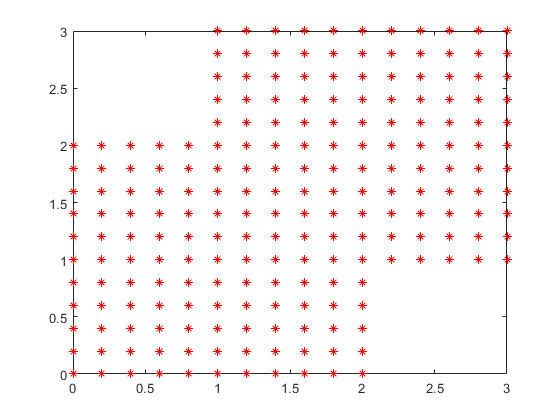

h = 0.2;


%Generating square base (0,3)^2
omega.o = [0,0];
omega.x = 3;
omega.y = 3;
omega.h = h;

omega = genRectMesh2D(omega);


%Plotting in little animation, how the index are counted
% animate(omega);

%Creating upper left and lowwer right square

%Top left
tlSquare.o = [0, 2];
tlSquare.x = 1;
tlSquare.y = 1;
tlSquare.h = h;

tlSquare = genRectMesh2D(tlSquare);

%Lower right
drSquare.o = [2, 0];
drSquare.x = 1;
drSquare.y = 1;
drSquare.h = h;

drSquare = genRectMesh2D(drSquare);

%Subtracting the Geometry from omega

omega = meshSubtract(omega,tlSquare, "ctl"); %Edge: Corner Top Left
omega = meshSubtract(omega,drSquare, "cdr"); %Edge: Corner Down Right
plot(omega.pointMat(:,1),omega.pointMat(:,2),'r*');


% animate(omega);

Wir könnten so vorgehen, dass wir bereits davor uns merken, was zum Rand und was zum Inneren gehört, oder eine Methode erstellen, die beim erstellen einer Nachbarschaftskorrespondenz Tabelle, den Rand von dem inneren trennt (wenn nicht vier Einträge möglich)

## Assemble and solve the matrix

First we have to define the functions $f,g \in C^2(\Omega)$, which define our right hand side and the boundary conditions

f = @(x) 5*pi^2.*sin(pi.*x(:,1)).*sin(2*pi*x(:,2));
g = @(x) 0;

Further we need to assemble the oh schreibe ja auf Deutsch, naja egal. Danach möchte ich die Systemmatrix assemblieren.

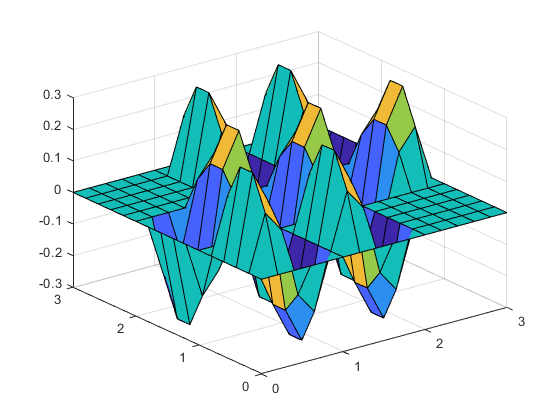

[Ah,bh] = assemble(omega,g,f);
u = Ah\bh;
visualize(omega,u);

Zur Fehlerabschätzung analytische Lösung

anaSol = @(x) sin(pi*x(1)).*sin(2*pi*x(2));
infty_err = infty_error(omega,u,anaSol)

infty_err = 0.2863

## Konvergenz illustrieren

infty_err = 	1.0e+-29 *

    0.1050
         0
         0
         0
         0
         0
         0


infty_err = 	1.0e+-14 *

    0.0000
    0.2733
         0
         0
         0
         0
         0


infty_err =     0.0000
    0.0000
    0.5697
         0
         0
         0
         0


infty_err =     0.0000
    0.0000
    0.5697
    0.1062
         0
         0
         0


infty_err =     0.0000
    0.0000
    0.5697
    0.1062
    0.0247
         0
         0


infty_err =     0.0000
    0.0000
    0.5697
    0.1062
    0.0247
    0.0061
         0


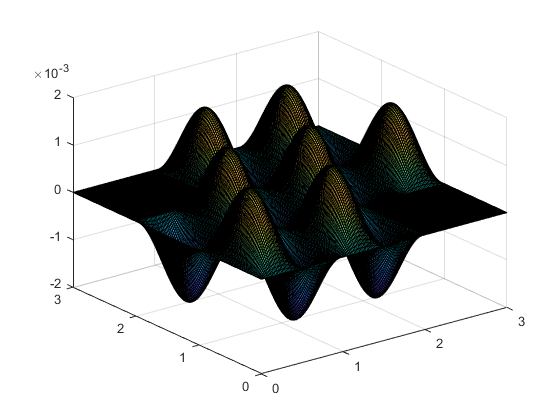

infty_err =     0.0000
    0.0000
    0.5697
    0.1062
    0.0247
    0.0061
    0.0015



%Testing 
h = 2.^(0:-1:-6);
t = zeros(numel(h),1);
infty_err = zeros(numel(h),1);
for k = 1:numel(h)
    tic
    
    
    %Generating square base (0,3)^2
    omega.o = [0,0];
    omega.x = 3;
    omega.y = 3;
    omega.h = h(k);
    
    omega = genRectMesh2D(omega);
    
    
    %Plotting in little animation, how the index are counted
    % animate(omega);
    
    %Creating upper left and lower right square
    
    %Top left
    tlSquare.o = [0, 2];
    tlSquare.x = 1;
    tlSquare.y = 1;
    tlSquare.h = h(k);
    
    tlSquare = genRectMesh2D(tlSquare);
    
    %Lower right
    drSquare.o = [2, 0];
    drSquare.x = 1;
    drSquare.y = 1;
    drSquare.h = h(k);
    
    drSquare = genRectMesh2D(drSquare);
    
    %Subtracting the Geometry from omega
    
    omega = meshSubtract(omega,tlSquare, "ctl"); %Edge: Corner Top Left
    omega = meshSubtract(omega,drSquare, "cdr"); %Edge: Corner Down Right
    
    f = @(x) 5*pi^2.*sin(pi.*x(:,1)).*sin(2*pi*x(:,2));
    g = @(x) 0;
    [Ah,bh] = assemble(omega,g,f);
    u = Ah\bh;
    visualize(omega,u);
    anaSol = @(x) sin(pi*x(1)).*sin(2*pi*x(2));
    infty_err(k) = infty_error(omega,u,anaSol)

t(k) = toc;
end

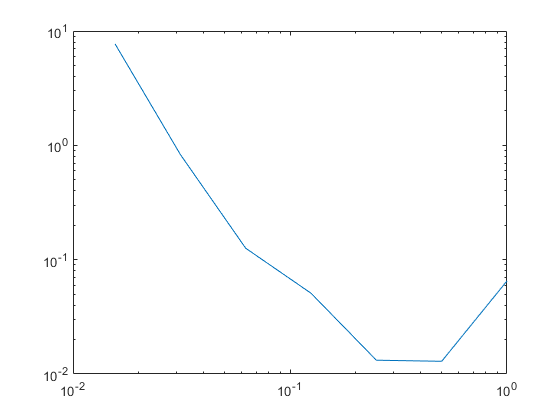

loglog(h,t)

### Generate Meshing

function OmegaHBar = genRectMesh2D(omeg)
%Input is a struct specifying the origin the X-Length, the Y-Length and the
%Meshsize h
    if mod(omeg.x,omeg.h) ~= 0 || mod(omeg.y,omeg.h) ~= 0
        error("X-Length or Y-Length are not applicable with the Meshsize of h");
    end
    
    nX = round(omeg.x/omeg.h);
    nY = round(omeg.y/omeg.h);
    N = (nX+1).*(nY+1);
    OmegaHBar = omeg;
    OmegaHBar.pointMat = zeros(N,2);
    for kY = 0:nY
        for kX = 0:nX
            OmegaHBar.pointMat(kY*(nX+1) + (kX + 1),:) = [omeg.o(1) + kX *omeg.h, omeg.o(2) + omeg.y - kY * omeg.h];
        end
    end
end

function OmegaHBar = meshSubtract(Omega, subOmega, edge)
%Subtracts a rectangular mesh from an arbitrary cubic Mesh while keeping the
%edges
if subOmega.h ~= Omega.h
    error("Meshsizes h are different");
end
h = subOmega.h;

if mod(subOmega.o(1)-Omega.o(1), h) ~= 0 || mod(subOmega.o(2)-Omega.o(2), h) ~= 0
    error("Origins are not a multiple of h appart from each other")
end


innerPoints = edgeCase(edge, subOmega, h);

innerPoints = genRectMesh2D(innerPoints);



OmegaHBar = Omega; %Take old settings even tough it may have been altered
OmegaHBar.pointMat = meshSubtractWithEdge(Omega.pointMat,innerPoints.pointMat);


end

function Omega = meshSubtractWithEdge(pM, pMSub)
%Input is the point Matrix of a area and an area you want to subtract it
%from - output is the point Matrix of pM without pMSub
%Could be implemented faster
isIn = false(size(pM,1),1);
lastSuccesful = 1;
for k1 = 1:size(pMSub,1)
    for k2 = lastSuccesful:size(pM,1)
        if equalEps(pMSub(k1,:),pM(k2,:))
            lastSuccesful = k2;
            isIn(k2) = true;
            break;
        end
    end
end
Omega = pM(~isIn,:);
end


function equalEps = equalEps(x, y)
%Basicly a more robust "=="
    if norm(x-y) < 1e4*eps(min(norm(x),norm(y)))
        equalEps = true;
    else
        equalEps = false;
    end
end

function innerPoints = edgeCase(edge, subOmega, h)
%Check which border to subtract and which to keep
%Inner
%Fun Fact: there are /sum_(k=1)^n nchosek(n,k) = 2^n symmetries
%In this 2D Case there are 4 Faces, so there are 16 possibilities (1 4 6 4
%1)
%For a cube there would be (1 6 15 20 15 6 1) ways of edge distribution
if edge == "i"
    innerPoints.x = subOmega.x - 2*h;
    innerPoints.y = subOmega.y - 2*h;
    innerPoints.o = subOmega.o + [h, h];
    
    %Single
elseif edge == "st" %single top
    innerPoints.x = subOmega.x - 2*h;
    innerPoints.y = subOmega.y - h;
    innerPoints.o = subOmega.o + [h, h];
    
elseif edge == "sl"
    innerPoints.x = subOmega.x - h;
    innerPoints.y = subOmega.y - 2*h;
    innerPoints.o = subOmega.o + [0, h];
    
elseif edge == "sr"
    innerPoints.x = subOmega.x - h;
    innerPoints.y = subOmega.y - 2*h;
    innerPoints.o = subOmega.o + [h, h];
    
elseif edge == "sd"
    innerPoints.x = subOmega.x - 2*h;
    innerPoints.y = subOmega.y - h;
    innerPoints.o = subOmega.o + [h, 0];
    %Double  
elseif edge == "dt" % ||    ||
    innerPoints.x = subOmega.x - 2*h;
    innerPoints.y = subOmega.y;
    innerPoints.o = subOmega.o + [h, 0];
    
    
elseif edge == "dd" % __--
    innerPoints.x = subOmega.x;
    innerPoints.y = subOmega.y - 2*h;
    innerPoints.o = subOmega.o + [0, h];
    
    %Corner (Corner indicates where the boarder is removed)
    %only the possition of innerPoints.o changes
elseif edge == "ctl"
    innerPoints.x = subOmega.x - h;
    innerPoints.y = subOmega.y - h;
    innerPoints.o = subOmega.o + [0, h];
    
elseif edge == "ctr"
    innerPoints.x = subOmega.x - h;
    innerPoints.y = subOmega.y - h;
    innerPoints.o = subOmega.o + [h, h];
    
elseif edge == "cdl"
    innerPoints.x = subOmega.x - h;
    innerPoints.y = subOmega.y - h;
    innerPoints.o = subOmega.o + [0, 0];
    
elseif edge == "cdr"
    innerPoints.x = subOmega.x - h;
    innerPoints.y = subOmega.y - h;
    innerPoints.o = subOmega.o + [h, 0];
    
    
    %Tube Position where border should remain
elseif edge == "tt"
    innerPoints.x = subOmega.x;
    innerPoints.y = subOmega.y - h;
    innerPoints.o = subOmega.o + [0, 0];
    
elseif edge == "tl"
    innerPoints.x = subOmega.x - h;
    innerPoints.y = subOmega.y;
    innerPoints.o = subOmega.o + [h, 0];
    
elseif edge == "tr"
    innerPoints.x = subOmega.x - h;
    innerPoints.y = subOmega.y;
    innerPoints.o = subOmega.o + [0, 0];
    
elseif edge == "td"
    innerPoints.x = subOmega.x;
    innerPoints.y = subOmega.y - h;
    innerPoints.o = subOmega.o + [0, h];
    
    %All
    endif edge == "all"
    innerPoints.x = subOmega.x;
    innerPoints.y = subOmega.y;
    innerPoints.o = subOmega.o + [0, 0];
end

innerPoints.h = h;
end


### Fun and visualization

function animate(omega)
%Animates the mesh given by the struct animate
figure;
plot(omega.o(1),omega.o(2),'ro');
xlim([omega.o(1),omega.o(1)+omega.x])
ylim([omega.o(2),omega.o(2)+omega.y])
hold on
n = size(omega.pointMat,1);
for k=1:n
    color = ones(3,1)*(k/n);
    plot(omega.pointMat(k,1),omega.pointMat(k,2),'Color',color,"Marker",'o')
    
    drawnow
    pause(1/n)
end
hold off
end


function visualize(omega, u)
    pM = omega.pointMat;
    h = omega.h;
    o = omega.o;
    x = omega.x;
    y = omega.y;
    n = size(pM,1);

    if n ~= size(u)
        error("Die Inputwerte haben verschiedene Groessen");
    end
    %Determining the most outer region, easiest and maybe only way to plot
    %it with surf
    xOut = o(1):h:o(1)+x;
    yOut = o(2):h:o(2)+y;
    [X,Y] = meshgrid(xOut,yOut);
    nOut = size(X,1);
    Z = zeros(nOut,nOut);
    idx = 1;
    for ky = nOut:-1:1
        for kx = 1:nOut
%             [X(kx,ky),Y(kx,ky)] Das ist falsch - deshlab vertauscht - bin
%             jetz aber zu müde zu überprüfen wieso
            if equalEps([xOut(kx), yOut(ky)], pM(idx,:)) %the same as xOut(kx), yOut(ky)  %%Y(kx,ky),X(kx,ky)
                Z(kx,ky) = u(idx);
                idx = idx + 1;
                if idx > n
                    break;
                end
            end
        end
        if idx > n
           break;
        end
    end
    
    surf(X,Y,Z);
end

### Calculation

function idxA = findNeighbor(currentIdx, omega) %[idxT, idxL, idxR, idxD]
    pM = omega.pointMat;
    refPoint = pM(currentIdx,:);
    h = omega.h;
    n = size(pM,1);
    idxA = nan(4,1);
%NOTE FOR EFFICIENCY TRY TO FIND OUT WHY +2h is of need
    
%Go left direction
    idx = currentIdx - 1;
    if idx ~= 0 && equalEps(pM(idx,:),refPoint + [-h 0])
        idxA(2) = idx;
    end
    
    while idx ~= 0  && pM(idx,2) <= refPoint(2) + 2*h %stops if out of reach
        if equalEps(pM(idx,:), refPoint + [0 h])
            idxA(1) = idx;
            break;
        end
        idx= idx - 1;
    end
       
    %Go right direction
    idx = currentIdx + 1;
    if idx ~= n + 1 && equalEps(pM(idx,:),refPoint + [h 0])
        idxA(3) = idx;
    end
    while idx ~= n + 1 && pM(idx,2) >= refPoint(2) - 2*h %stops
            if equalEps(pM(idx,:), refPoint + [0 -h])
                idxA(4) = idx;
                break;
            end
            idx = idx + 1;
     end
end

function [neighbor,edge] = neighbor(omega)
    h = omega.h;
    n = size(omega.pointMat,1);
    neighbor = sparse(n,n);
    edge = false(n,1);
    for k1 = 1:n
       idx = findNeighbor(k1, omega); % [idxT, idxL, idxR, idxD] 
       % WARNING IMPROVEMENT SHOULD BE MADE
       % We throw away the important information if top, left, right or down neighbor, which is inly for this implementation okay, since we treat all neighbors the same
       if any(isnan(idx))
           edge(k1) = true;
       end
       for k2 = idx
           if ~isnan(k2)
               neighbor(k1, k2) = 1;
           end
       end
    end
end

function [Ah, bh] = assemble(omega, g, f)
    %Assembles the system Matrix and the right hand side
    pM = omega.pointMat;
    h = omega.h;
    n = size(omega.pointMat,1);
    [neighbors, edge] = neighbor(omega);
    Ah = (1/h.^2)*(4*sparse(eye(n))+ neighbors);
    gVal = g(pM).* edge;
    fVal = f(pM).* ~edge;
    bh = gVal + fVal;
end

function infty_err = infty_error(omega, u, anaSol)
    pM = omega.pointMat;
    infty_err = max(anaSol(pM) - u);
end
